# BallBot - 2D XZ Model

#### Defining:


$$\gamma = m_w\cdot(R_b+R_w)+m_r\cdot l \\
\eta = \frac{R_b}{R_w^2} + \frac{1}{R_w} \\
m_t = m_b + m_w + m_r \\
I_t = \frac{I_w}{R_w^2} + \frac{I_b}{R_b^2} \\
\lambda = m_w\cdot \left(R_b+R_w\right)^2 + m_r \cdot l^2 + I_r + I_w \cdot \left(\frac{R_b^2}
{R_w^2} + 2\cdot\frac{R_b}{R_w} + 1 \right)$$


clc; clear all

syms g m_b m_w m_r I_b I_w I_r ...
    R_b R_w l ...
    gamma eta lambda m_t I_t ...
    x_1 x_2 x_3 x_4 T ...
    b_ball b_ground ...
    theta_r theta_dot_r x x_dot

M = [(m_t + I_t)                    (cos(x_2)*gamma - I_w*eta);
    (cos(x_2)*gamma - I_w*eta)                  lambda        ]     

$$M = \left(\begin{array}{cc} I_{t}+m_{t} & \gamma \,\cos\left(x_{2}\right)-I_{w}\,\eta \\ \gamma \,\cos\left(x_{2}\right)-I_{w}\,\eta & \lambda \end{array}\right)$$

C = [-x_4^2*sin(x_2)*(gamma); 0]

$$C = \left(\begin{array}{c} -\gamma \,{x_{4}}^{2}\,\sin\left(x_{2}\right)\\ 0 \end{array}\right)$$

D = 0;

G = [0;
    -g*sin(x_2)*gamma]

$$G = \left(\begin{array}{c} 0\\ -g\,\gamma \,\sin\left(x_{2}\right) \end{array}\right)$$

Q = [T/R_w; -T*R_b/R_w]

$$Q = \left(\begin{array}{c} \frac{T}{R_{w}}\\ -\frac{R_{b}\,T}{R_{w}} \end{array}\right)$$

aux = simplify(inv(M)*(Q-C-G-D))

$$aux = \begin{array}{l} \left(\begin{array}{c} \frac{T\,\lambda +R_{b}\,T\,\gamma \,\cos\left(x_{2}\right)-I_{w}\,R_{b}\,T\,\eta +R_{w}\,\gamma \,\lambda \,{x_{4}}^{2}\,\sin\left(x_{2}\right)-R_{w}\,g\,\gamma^{2}\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)+I_{w}\,R_{w}\,\eta \,g\,\gamma \,\sin\left(x_{2}\right)}{\sigma_{1}}\\ -\frac{I_{t}\,R_{b}\,T-I_{w}\,T\,\eta +R_{b}\,T\,m_{t}+T\,\gamma \,\cos\left(x_{2}\right)+R_{w}\,\gamma^{2}\,{x_{4}}^{2}\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)-I_{t}\,R_{w}\,g\,\gamma \,\sin\left(x_{2}\right)-R_{w}\,g\,\gamma \,m_{t}\,\sin\left(x_{2}\right)-I_{w}\,R_{w}\,\eta \,\gamma \,{x_{4}}^{2}\,\sin\left(x_{2}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{w}\,\left(-{I_{w}}^{2}\,\eta^{2}+2\,I_{w}\,\eta \,\gamma \,\cos\left(x_{2}\right)-\gamma^{2}\,{\cos\left(x_{2}\right)}^{2}+I_{t}\,\lambda +\lambda \,m_{t}\right) \end{array}$$

## Space - State For the X-Z Plane


$$x_1 = x \rightarrow Ball \,position\\
x_2 = \theta_r \rightarrow Robot\,pitch\,angle\\
x_3 = \dot{x} \rightarrow Ball\,linear\,velocity\\
x_4 = \dot{\theta_r} \rightarrow Robot\,pitch\,rate\\$$



$$\left(\begin{array}{c} 
\dot{x_1} \\ 
\dot{x_2} \\ 
\dot{x_3} \\ 
\dot{x_4} 
\end{array}\right) 
= \left(\begin{array}{c} 
x_3 \\ 
x_4 \\
\frac{T\,\lambda 
	+R_b \,T\,\gamma \,\cos \left(x_2 \right)
	-I_w \,R_b \,T\,\eta 
	+R_w \,\gamma \,\lambda \,{x_4 }^2 \,\sin \left(x_2 \right)
	-R_w \,g\,\gamma^2 \,\cos \left(x_2 \right)\,\sin \left(x_2 \right)
	+I_w \,R_w \,\eta \,g\,\gamma \,\sin \left(x_2 \right)}
{R_w \,{\left(-{I_w }^2 \,\eta^2 +2\,I_w \,\eta \,\gamma \,\cos \left(x_2 \right)-\gamma^2 \,{\cos \left(x_2 \right)}^2 +I_t \,\lambda +\lambda \,m_t \right)}} \\
\frac{-I_t \,R_b \,T
	+I_w \,T\,\eta 
	-R_b \,T\,m_t 
	-T\,\gamma \,\cos \left(x_2 \right)
	-R_w \,\gamma^2 \,{x_4 }^2 \,\cos \left(x_2 \right)\,\sin \left(x_2 \right)
	+I_t \,R_w \,g\,\gamma \,\sin \left(x_2 \right)-R_w \,g\,\gamma \,m_t \,\sin \left(x_2 \right)
	+I_w \,R_w \,\eta \,\gamma \,{x_4 }^2 \,\sin \left(x_2 \right)}
{R_w \,{\left(-{I_w }^2 \,\eta^2 +2\,I_w \,\eta \,\gamma \,\cos \left(x_2 \right)-\gamma^2 \,{\cos \left(x_2 \right)}^2 +I_t \,\lambda +\lambda \,m_t \right)}} 



\end{array} \right) $$


X_dot = [x_3; x_4; aux(1); aux(2)];
A_sym = jacobian(X_dot, [x_1, x_2, x_3, x_4])

B_sym = jacobian(X_dot, T)

$$B\_sym = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ \frac{\lambda -I_{w}\,R_{b}\,\eta +R_{b}\,\gamma \,\cos\left(x_{2}\right)}{\sigma_{1}}\\ -\frac{R_{b}\,m_{t}-I_{w}\,\eta +\gamma \,\cos\left(x_{2}\right)+I_{t}\,R_{b}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{w}\,\left(-{I_{w}}^{2}\,\eta^{2}+2\,I_{w}\,\eta \,\gamma \,\cos\left(x_{2}\right)-\gamma^{2}\,{\cos\left(x_{2}\right)}^{2}+I_{t}\,\lambda +\lambda \,m_{t}\right) \end{array}$$

# BallBot Physical Parameters

g_value = 9.81;                 % m/s^2

%% BalBot V2
robot = struct( ...
    'm_b',      1.0 * 0.580, ... % kg
    'm_w',      0.03873, ...     % kg
    'm_r',      1.0 * 2.18, ...  % kg
    'I_b',      0.005499, ...    % kg*m^2 (X-Z Plane Inertias)
    'I_w',      0.000021, ...    % kg*m^2 (X-Z Plane Inertias)
    'I_r',      0.008505, ...    % kg*m^2 (X-Z Plane Inertias)
    'R_b',      0.12, ...        % m
    'R_w',      0.035, ...       % m
    'l',        1.0 * 0.194);      % m);

gamma_value = robot.m_w*(robot.R_b+robot.R_w) + robot.m_r*robot.l;
eta_value = (robot.R_b/(robot.R_w^2)) + (1/robot.R_w);
m_t_value = robot.m_b + robot.m_w + robot.m_r;
I_t_value = (robot.I_w/(robot.R_w^2)) + (robot.I_b/(robot.R_b^2));
lambda_value = (robot.m_w*(robot.R_b+robot.R_w)^2) + (robot.m_r*robot.l^2) + robot.I_r + (robot.I_w*(((robot.R_b^2)/(robot.R_w^2)) + (2*(robot.R_b/robot.R_w)) + 1));

x_1_value = 0; x_2_value = 0; x_3_value = 0; x_4_value = 0; T_value = 0;

A = double(subs(A_sym, [I_t, I_w, R_b, R_w, T, eta, g, gamma, lambda, m_t, x_2, x_4], ...
    [I_t_value, ...
    robot.I_w, ...
    robot.R_b, ...
    robot.R_w, ...
    T_value, ...
    eta_value, ...
    g_value, ...
    gamma_value, ...
    lambda_value, ...
    m_t_value, ...
    x_2_value, ...
    x_4_value]))

A =          0         0    1.0000         0
         0         0         0    1.0000
         0  -15.9929         0         0
         0  119.9751         0         0


B = double(subs(B_sym, [lambda, I_w, R_b, R_w, eta, gamma, m_t, I_t, x_2], ...
    [lambda_value, ...
    robot.I_w, ...
    robot.R_b, ...
    robot.R_w, ...
    eta_value, ...
    gamma_value ...
    m_t_value, ...
    I_t_value, ...
    x_2_value]))

B =          0
         0
   36.4423
 -206.3541


eig(A)

ans =          0
         0
   10.9533
  -10.9533


Q = diag([0.1; 10; 1; 1]);
R = 1;

C = eye(4);
sys = ss(A, B, C, D);
length(A);
rank(ctrb(A, B))

ans = 4

rank(obsv(A, C))

ans = 4

K = lqr(sys, Q, R)

K =    -0.3162   -5.7336   -1.2756   -1.2675


## Simulating the Dynamics of the System

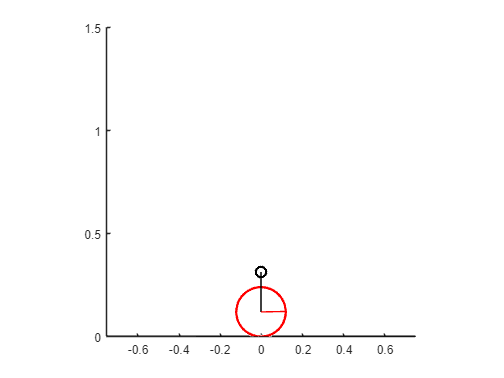

x_ref = 0; theta_ref = deg2rad(0); x_dot_ref = 0; theta_dot_ref = 0;
X_ref = [x_ref; theta_ref; x_dot_ref; deg2rad(theta_dot_ref)];
out = sim("XZSim.slx", 20);
x = out.y.Data(:, 1);
theta = out.y.Data(:, 2);
x_dot = out.y.Data(:, 3);
theta_dot = out.y.Data(:, 4);
T = out.T.Data(:, 1);

plot_animation = true;

if plot_animation
    for i=1:length(theta)
        if i == 1
            axis equal 
            line([-15 15],[0 0],'Color','k', 'LineWidth', 2)
        end
    
        axis([x(i)-0.75 x(i)+0.75 0 1.5])
    
        h(1)=viscircles([x(i) robot.R_b], robot.R_b);
        h(2)=viscircles([(x(i)+(robot.l*sin(theta(i)))) (robot.R_b+(robot.l*cos(theta(i))))], 0.025, 'Color','k');
        h(3)=line([x(i) (x(i)+robot.l*sin(theta(i)))], [robot.R_b ((robot.R_b)+robot.l*cos(theta(i)))],'Color','k');
        h(4)=line([x(i) x(i)+robot.R_b*cos((x(i)/robot.R_b))], [robot.R_b robot.R_b+robot.R_b*-sin((x(i)/robot.R_b))],'Color','r');
        pause(0.1)
    
        if i ~= length(theta)
            delete(h)
        end
    end
end

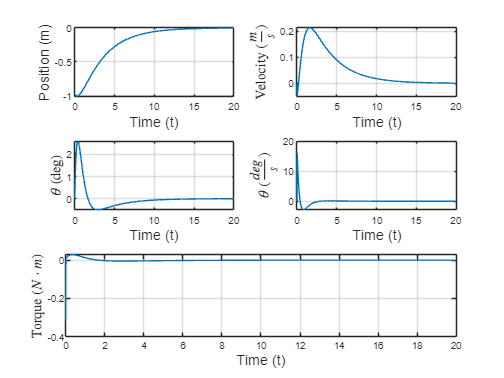

subplot(3, 2, 1);
plot(out.tout, x);
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('Position (m)', 'FontSize', 12);

subplot(3, 2, 2);
plot(out.tout, x_dot);
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('Velocity ($\frac{m}{s}$)', 'Interpreter', 'latex', 'FontSize', 12);

subplot(3, 2, 3);
theta_deg = theta*180/pi;
plot(out.tout, theta_deg);
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('$\theta$ (deg)', 'Interpreter', 'latex', 'FontSize', 12);

subplot(3, 2, 4);
theta_dot_deg = theta_dot*180/pi;
plot(out.tout, theta_dot_deg);
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('$\theta$ ($\frac{deg}{s}$)', 'Interpreter', 'latex', 'FontSize', 12);
                                   
subplot(3, 2, [5, 6]);
plot(out.tout, T);
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('Torque ($N\cdot m$)', 'Interpreter', 'latex', 'FontSize', 12);

save_data = false;
if save_data
    data = [out.tout, x, x_dot, theta_deg, theta_dot_deg, T];
    save("output.mat", "data")
end